# Ejercicios de optimización de funciones

## Encontrar un máximo o un mínimo local

7.3 Locate the minimum of the function 

*f *(*x*) = 3 + 6*x *+ 5*x^*2 + 3*x^*3 + 4*x^*4 

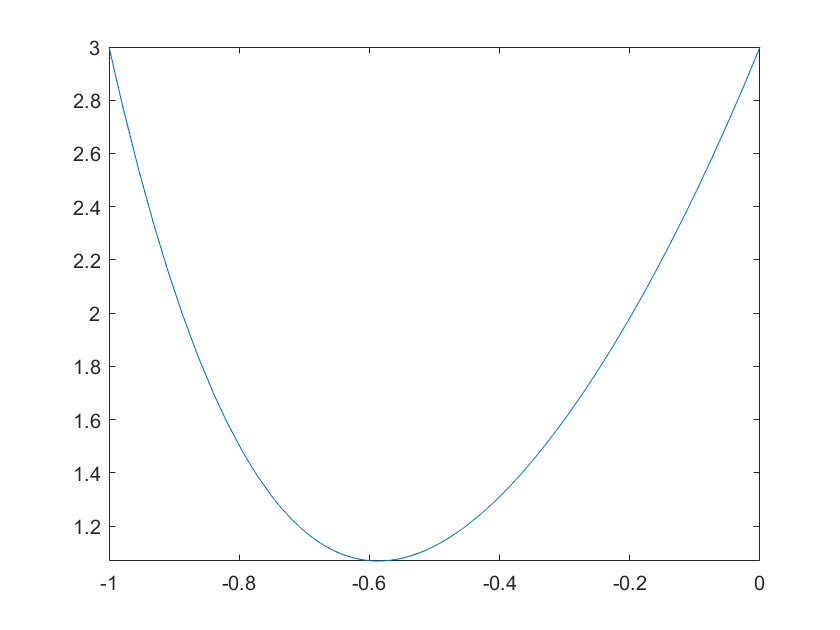

%
f=@(x) 3 + 6*x + 5*x.^2 + 3*x.^3 + 4*x.^4;
g=@(x) -1;
fplot(f,[-1,0])

%minimo goldenSS
[x,i]=goldenSS(f,-1,0)

x = -0.5867

i = 75

[x,i]=gss(f,-1,0)

x = -0.5000

i = 0

%minimo newtonOpt
[x,i,max]=newtonOpt(f,2)

x = -0.5867

i = 9

max = logical
   0


7.2 Determine the maximum and the corresponding value of x for the function 

*f *(*x*) = −*x^*2 + 8*x *− 12 

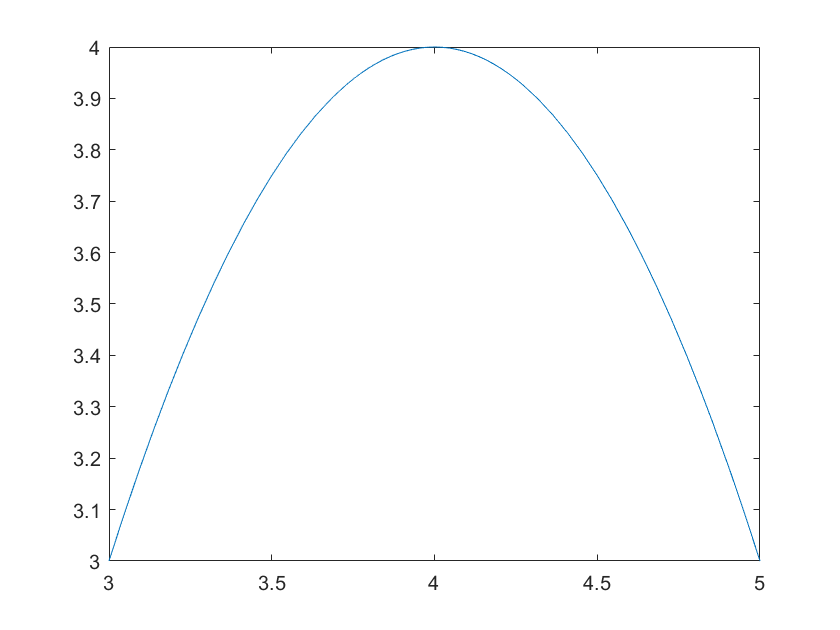

%
f=@(x) -x.^2+8*x-12;
fplot(f,[3,5])

%maximo goldenSS
[x,i]=goldenSS(@(x) -f(x),3,5)

x = 4.0000

i = 72

[x,i]=gss(@(x) -f(x),3,5)

x = 4.0000

i = 74

%maximo newtonOpt
[x,i,max]=newtonOpt(f,2)

x = 4

i = 1

max = logical
   1


7.4 Given 

*f *(*x*) = −1.5*x^*6 − 2*x^*4 + 12*x *

(a) Plot the function. 

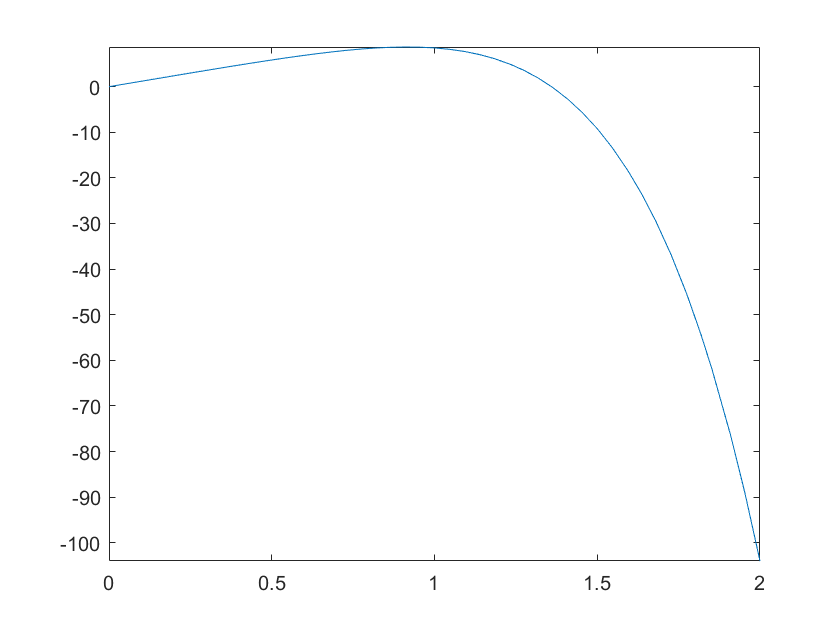

%
f=@(x) -1.5*x.^6-2*x.^4+12*x;
fplot(f,[0,2])

(b) Use analytical methods to prove that the function is con­cave for all values of *x*. 

f´(x)=-9x^5-8x^3+12

f´´(x)=-45x^4-24x^2 

Se puede observar que para todo x, se tiene que la segunda derivada es menor o igual a 0, que cumple con la condición de ser cóncava.

(c) Find the maximum *f*(*x*) and the corre­sponding value of *x*. 

%maximo goldenSS
[x,i]=goldenSS(@(x) -f(x),0,2)

x = 0.9169

i = 76

[x,i]=gss(@(x) -f(x),0,2)

x = 0.9169

i = 77

%maximo newtonOpt
[x,i,max]=newtonOpt(f,-2 )

x = 0.9169

i = 20

max = logical
   1


Problema de la presentación:

g= 9.81 m/s^2

z0= 100 m

v0= 55 m/s

m=80 kg

c= 15 kg/s

z=z0+(m/c) * (v0 +m*g/c)*(1- e^(-c*t/m)) - m*g*t/c 

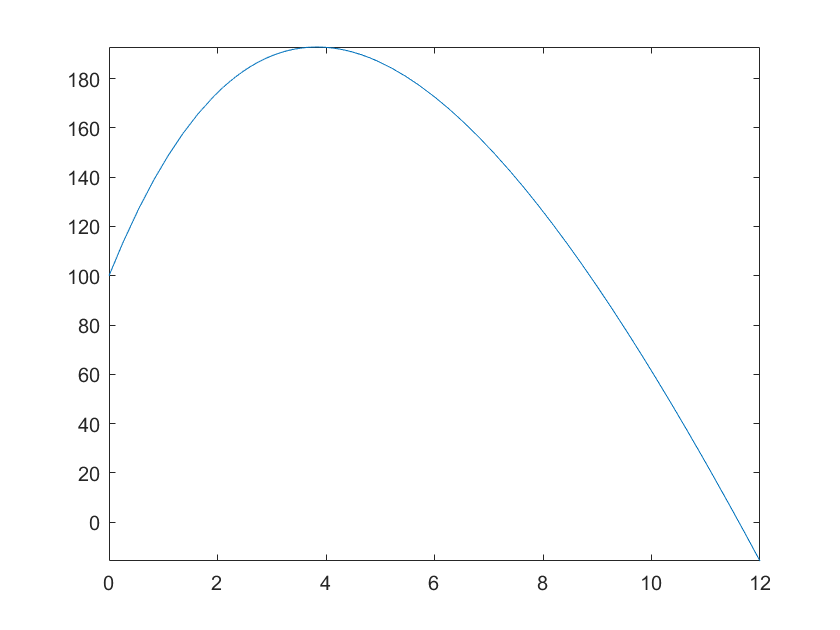

g=9.81;
z0=100;
v0=55;
m=80;
c=15;
f=@(t) z0+(m/c) * (v0 +m*g/c)*(1- exp(-c*t/m)) - m*g*t/c;
fplot(f,[0,12])

%maximo goldenSS
[x,i]=goldenSS(@(t) -f(t),2,5)

x = 3.8317

i = 74

[x,i]=gss(@(t) -f(t),2,5)

x = 3.8317

i = 75

%maximo newtonOpt
[x,i,max]=newtonOpt(f,-2 )

x = 3.8317

i = 6

max = logical
   1


Pruebas interpolación cuadrática

f=@(x) 3 + 6*x + 5*x.^2 + 3*x.^3 + 4*x.^4;
g=@(x) -1;
fplot(f,[-1,0])


[x,i]=interpolParab(f,-1,-0.2,-0.5)

x = -0.5867

i = 6

## Código de las funciones

Golden section search

function [res,i]=goldenSS(f,a,b)
    phi=(2-(1+sqrt(5))/2);
    e=(b-a) * phi;
    c = a + e;
    d = b - e;
    fc = f(c);
    fd = f(d);
    MAX=1000;
    i=0;
    while abs(b-a)/(abs(c)+abs(d))>eps && i<MAX
        i=i+1;
        if fc < fd
            b = d;
            d = c;
            c = a + (b-a) * phi;
            fd = fc;
            fc = f(c);
        
        else
            a = c;
            c = d;
            d = b - (b-a) * phi;
            fc = fd;
            fd = f(d);
        end
    end
    res=(a+b)/2;
end

function [x,i]=gss(f,a,b)
    phi=(1+sqrt(5))/2 -1;
    x=(a+b)/2;
    i=0;
    MAX=1000;
    while (abs(b-a)/x)>eps && i<MAX
        d=phi*(b-a);
        x1=a+d;
        x2=b-d;
        if f(x2)>f(x1)
            a=x2;
        else
            b=x1;
        end
        x=(a+b)/2;
        i=i+1;
    end
end

Newton optimization

function [xfin,i,max]=newtonOpt(f,xi)
    syms x
    fsym=sym(f);
    dfs=diff(fsym);
    if dfs==0, error('La función es constante, no tiene máximos'), end
    df=matlabFunction(dfs);
    dfs2=diff(fsym,2);
    if dfs2==0,error('no hay maximos locales, el máximo se encuentra en un extremo'),end
    if isempty(symvar(dfs2))
        d2=matlabFunction(dfs2,'vars',x);
        df2=@(x) ones(size(x))*d2(x);
    else
        df2=matlabFunction(dfs2);
    end
    xp=xi;
    MAX=1000;
    i=0;
    
   
    xfin=xp-df(xp)/df2(xp);
    while abs((xfin-xp)/xfin)>eps && i<MAX
        xp=xfin;
        xfin=xp-df(xp)/df2(xp);
        i=i+1;
    end
    
    max=false;
    if(df2(xfin)<0)
        max=true;
    end
end

Interpolación parabólica

function [x,i]=interpolParab(f,x0,x1,x2)
    val=[x0 x1 x2];
    fval=[f(x0) f(x1) f(x2)];
    p=polyfit(val,fval,2);
    xp=x1;
    x=-p(2)/(2*p(1));
    i=1;
    MAX=100;
    x0=x1;
    x1=x2;
    x2=x;
    while abs((x-xp)/x)>eps && i<MAX && abs(x0-x1)>0.00001 && abs(x0-x2)>0.00001 && abs(x2-x1)>0.00001
        val=[x0 x1 x2];      
        fval=[f(x0) f(x1) f(x2)];
        p=polyfit(val,fval,2);
        xp=x;
        x=-p(2)/(2*p(1));
        x0=x1;
        x1=x2;
        x2=x;
        i=i+1;
    end
end